# Zadatak 3 - Klasifikacija govornika korišćenjem LPC koeficijenata

U ovom radu će biti predstavljena klasifikacija tri izgovorena broja, na osnovu trening seta od 30 izgovorenih cifara(numerisanih od 1-10) i evaulirana na osnovu test seta(numerisanih cifara 11-15). Klase:

- "jedan"

- "dva"

- "tri"

## 3.0 - Snimanje sekvenci

Fs = 8000; 
br_bita = 16;
br_kanala = 1;
audio_rec = audiorecorder(Fs, br_bita, br_kanala);
disp("Zapocnite govor.")

Zapocnite govor.



trajanje_sekvence = 1.5; 
recordblocking(audio_rec, trajanje_sekvence);
disp("Kraj snimanja.")

Kraj snimanja.



play(audio_rec);
sekvenca = getaudiodata(audio_rec);
fajl = '3.15.wav';
audiowrite(fajl,sekvenca, Fs)


% 1-10 - train set
% 11, 12, 13, 14, 15 - test set

[test, fs] = audioread('1.1.wav');

## 3.1 - Predobrada sekvenci

Filtracija je određena digitalnim bandpass butterworth filtrom. Dok je segmentacija odrađena kao u zadatku 1, na osnovu kratkovremenske enrgije, i iterativnim pomeranjem dva pokazivača na osnovu dodnjeg i gornjeg threshhold-a.

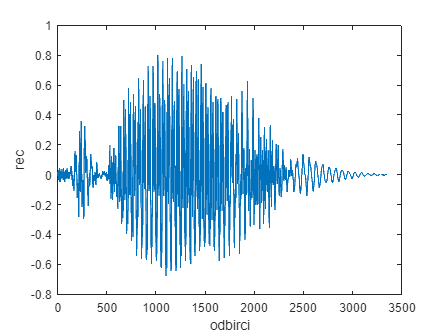

y = preprocessing(test,fs);
plot(y);
xlabel('odbirci')
ylabel('rec')

## 3.2 - Ekstrakcija obeležja na osnovu LPC-a

LPC (Linear Predictive Coding) analiza je tehnika koja se koristi za modeliranje i analizu govornih signala. Osnovna ideja LPC analize je da se govorni signal može aproksimirati linearnim autoregresivnim (AR) modelom, što znači da se sadašnji odbirci govornog signala mogu predvideti pomoću prethodnih odbiraka. Ovaj model se naziva "all-pole model" jer ima samo polove, odnosno ne sadrži nule. 

Od tih koeficijenata su formirana dva obeležja. 

- Razlika u minimumu i maksimumu i-tog koeficijenta

- Srednja vrednost i-tog koeficijenta, kroz vreme

Gde je $i=2$.

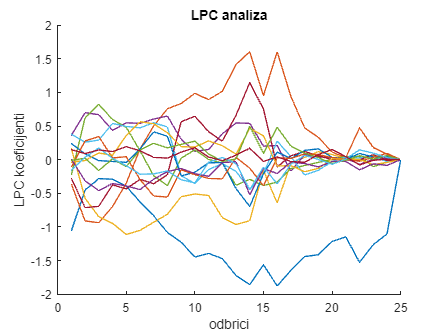

obelezja =     1.8770   -1.1331


obelezja = feature_extraction(y,fs)

## 3.3 - Klasifikacija govora uz knn klasifikator

K-najbližih suseda (KNN) klasifikator je jednostavan algoritam za mašinsko učenje koji se koristi za klasifikaciju novih uzoraka na osnovu sličnosti sa već poznatim podacima. Kada se primeni na nepoznati uzorak, KNN pronalazi K najbližih suseda iz obučavajućeg skupa podataka, koristeći neku mernu metriku udaljenosti, kao što je Euklidska udaljenost. Klasifikacija se vrši na osnovu većine klase suseda, gde novi uzorak dobija oznaku klase koju najčešće dele njegovi najbliži susedi. Ovde je prikazana klasifikacija prve snimljene sekvence, na osnovu trening seta od prvih 10 cifara, od svake klase respektivno. Klasifikator je uspesno klasifikovao prvu instancu trening seta.

klasa = cifer_recognition(test,fs);

mdl =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3]
           ScoreTransform: 'none'
          NumObservations: 30
                 Distance: 'euclidean'
             NumNeighbors: 3


  Properties, Methods


klasa

klasa = 1

## 3.4 - Konfuzione matrice i evaluacija sistema za obradu i prepoznavanje govora

Dalje su predstavljeni rezultati za test set sistema za prepoznavanje govora. Može se zaključiti da je algoritam solidan u klasifikaciji izgovorenih brojeva. Postoji nekoliko razloga zašto je loše klasifikovana "jedinica". S obzirom da jedinica u sebi sadrži glas n, usvojeni LPC model nije baš najsjajniji u modelovanju nazala zbog antirezonantnih svojstva tih glasova. Unapređenje bi moglo da se dostigne uvođenjem modela koji u sebi sadrži i nule. Bitno je napomenuti, da bi bilo potrebno odraditi analizu sa većim uzorkom, da bi donešeni zaključci bili robusniji.


    jedan=[];
    for i=11:15
        [test, fs] = audioread('1.' + string(i) + '.wav');
        jedan = [jedan cifer_recognition(test,fs)];
    end

    
    dva = [];
    for i=11:15
        [test, fs] = audioread('2.' + string(i) + '.wav');
        dva = [dva cifer_recognition(test,fs)];
    end

    
    tri=[];
    for i=11:15
        [test, fs] = audioread('3.' + string(i) + '.wav');
        tri = [tri cifer_recognition(test,fs)];
    end

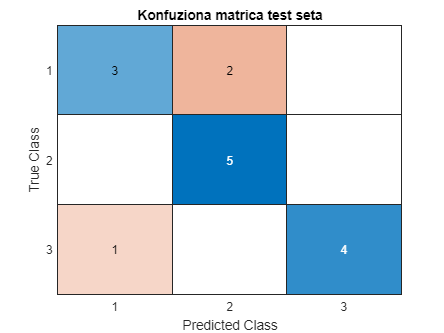

    
true_classes = [ones(1,5), ones(1,5)*2, ones(1,5)*3];
true_classes = true_classes';
predicted = [jedan, dva, tri];
predicted = predicted';
    
figure()
C = confusionmat(true_classes,predicted);
confusionchart(C)
title("Konfuziona matrica test seta")

Radi kompletnosti rada, dalje je predstavljena konfuziona matrica za trening set:

    jedan=[];
    for i=1:10
        [test, fs] = audioread('1.' + string(i) + '.wav');
        jedan = [jedan cifer_recognition(test,fs)];
    end

    
    dva = [];
    for i=1:10
        [test, fs] = audioread('2.' + string(i) + '.wav');
        dva = [dva cifer_recognition(test,fs)];
    end

    
    tri=[];
    for i=1:10
        [test, fs] = audioread('3.' + string(i) + '.wav');
        tri = [tri cifer_recognition(test,fs)];
    end

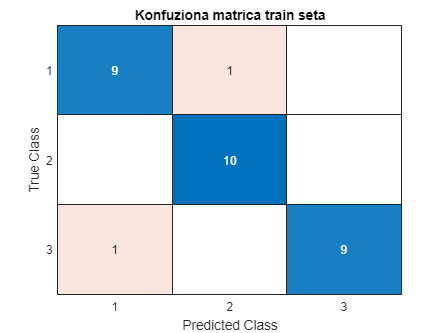

true_classes = [ones(1,10), ones(1,10)*2, ones(1,10)*3];
true_classes = true_classes';
predicted = [jedan, dva, tri];
predicted = predicted';
    
figure()
C = confusionmat(true_classes,predicted);
confusionchart(C)
title("Konfuziona matrica train seta")